# Borromean ring with  an extra B

单粒子的Hamiltonian为$H_0 =\epsilon_k \sigma_0 +\frac{\lambda }{m_a }\left(k_x \sigma_x +k_y \sigma_y \right)+B\sigma_z$，其中B是实数。

可以解得单粒子能谱为$\xi_{k,\pm } =\frac{k^2 }{2m_a }\pm \sqrt{{\left(\frac{\lambda }{m_a }\right)}^2 k_{\bot }^2 +B^2 }$

取$\frac{\lambda^2 }{2m_a }$作为能量的量纲，$\frac{\lambda^2 }{m_a }$ 做B的量纲，可以得到无量纲化的能量为


$$\xi =k^2 \pm 2\sqrt{k_{\perp }^2 +B^2 }$$


当$k_{\perp } =\sqrt{1-B^2 }$, $k_z =0$时，$\xi$ 取极值 $E_{\mathrm{th}} =-1-B^2$

当$k=0$ 时，$\xi_- =-2B$

因为$\xi_- -E_{\mathrm{th}} ={\left(B-1\right)}^2 \ge 0$

所以$E_{\mathrm{th}}$ 是系统的基态，在k空间有$U\left(1\right)$的简并性，并且当$B\ge 1$时，这种简并性消失。


$$E_{\mathrm{th}} =\left\lbrack \begin{array}{cc}
-1-B^2  & \mathrm{when}\;B<1\\
-2B & \mathrm{when}\;B\ge 1
\end{array}\right\rbrack$$


### 3 body

首先，在$\left(\lambda a_s \right)=0\ldotp 6,\;\eta =\frac{40}{6},\;\Lambda =1000,\;B=0$的情况下与之前的程序做对比

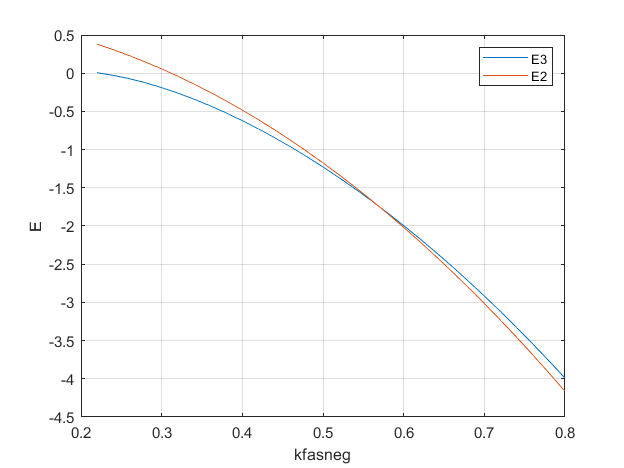

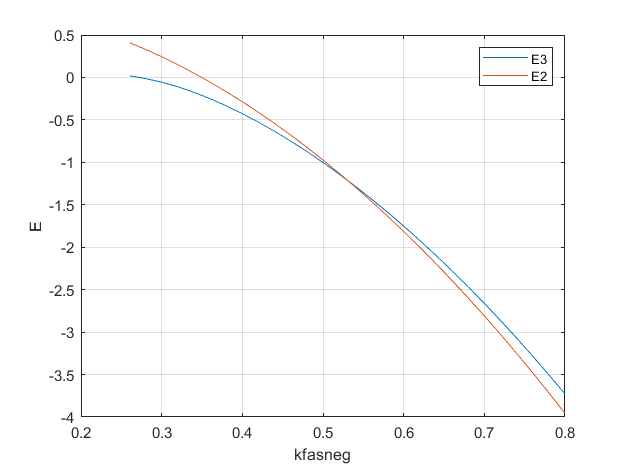

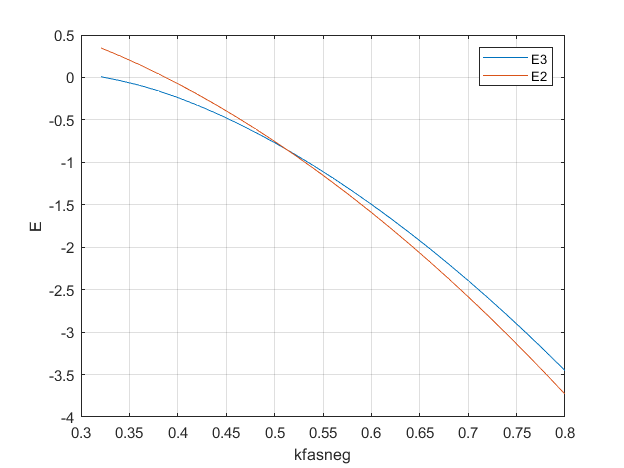

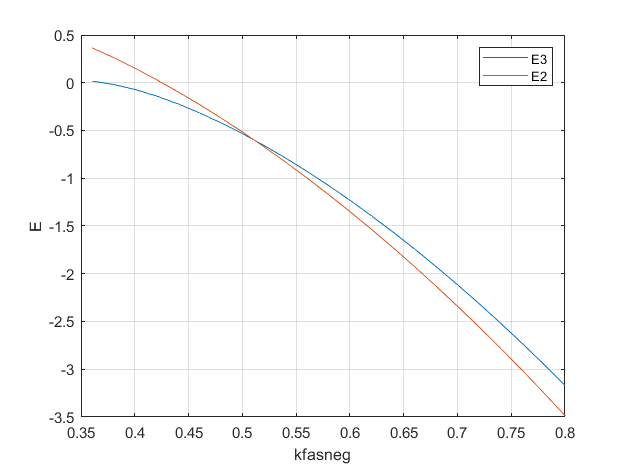

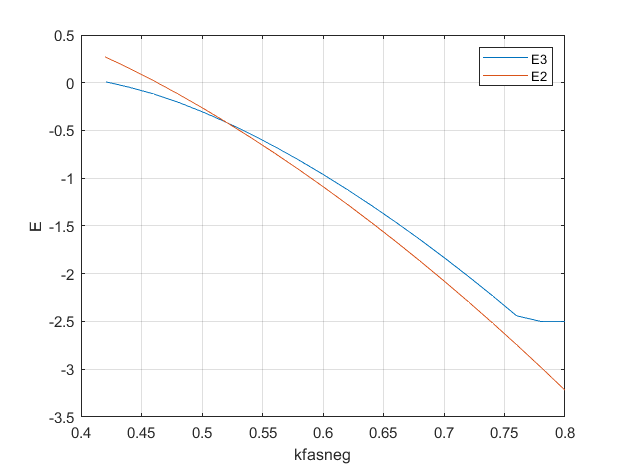

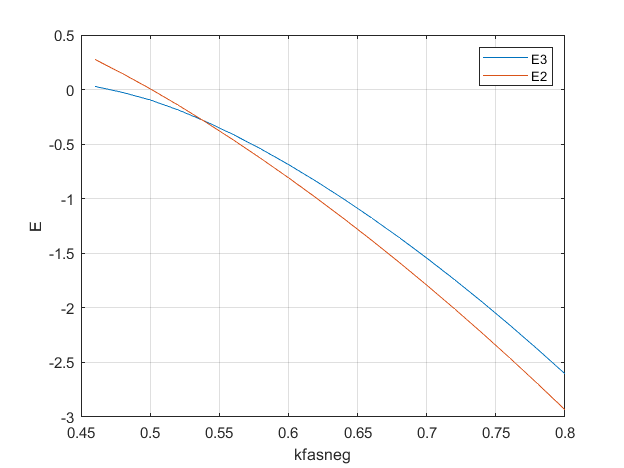

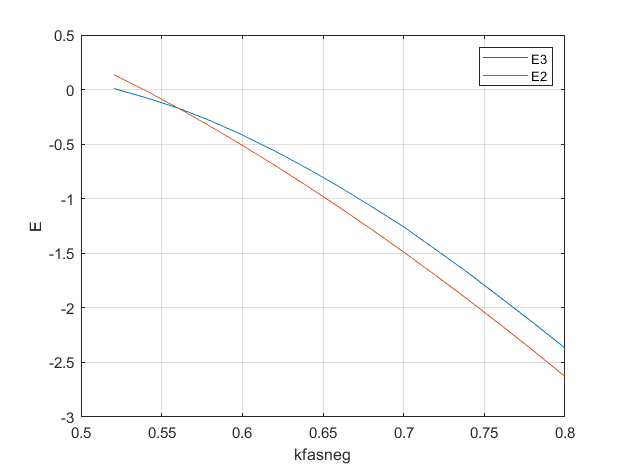

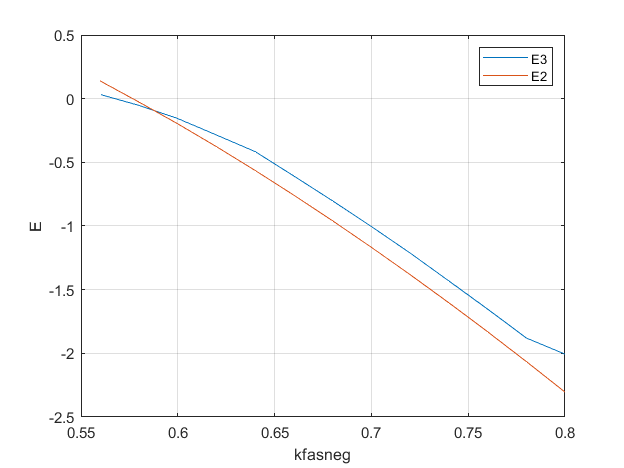

clear
warning off
kfasneg1=0.6; cutoff=1000; eta=40/6; 
t0=clock;
% allocate memory in advance
x=zeros(1,30);
rel1=x;rel2=x;


parfor i=1:30
    x(i)=-4+0.2*i;
    rel1(i)=borromeansolver(x(i),kfasneg1,cutoff,eta,0);
    rel2(i)=get3bodysol(x(i),kfasneg1,2,eta); 
end
% totoal running time
t=clock;
disp(['total running time :',num2str(etime(t,t0)),'s']);
% figure
figure
plot(x,real(rel1),"b")
hold on
plot(x,real(rel2),"r")
title('eig of coefficent matirx versus E3')
xlabel('E3')
ylabel('eigenvalue')
legend('borromeansolverxz','get3bodysol')
grid on

结果是一致的。

现在尝试不同的B的值。

clear
spmd
    warning off;
end

kfasneg1=0.6; cutoff=1000; eta=40/6;B=[0, 0.1, 0.5,0.9,1];
t0=clock;
% allocate memory in advance
x=zeros(1,30);
rel1=x;rel2=x;
x=linspace(-3,2,50);
figure
for j=1:length(B)
    Bi=B(j);
    parfor i=1:length(x)
        rel1(i)=borromeansolver(x(i),kfasneg1,cutoff,eta,Bi);   
    end
    plot(x,rel1)
    hold on
end
% totoal running time
t=clock;
disp(['total running time :',num2str(etime(t,t0)),'s']);
title('eig of coefficent matirx versus E3')
xlabel('E3')
ylabel('eigenvalue')
legend show
grid on

xlim([-4.00 2.00])
ylim([-0.231 0.169])
legend({'B=0','B=0.1','B=0.5','B=1'})

由于随着B的增大，${k^{\mathrm{min}} }_{\perp }$会逐渐的趋于0，能形成稳定的三体的束缚态的能力就会减小。所以束缚能会越来越小。

下面找当B取多大时，三体束缚能为0

clear
spmd
    warning off;
end
kfasneg1=0.6; cutoff=1000; eta=40/6;

当$B\approx 0\ldotp 794$时，不再有三体束缚态。


    x=linspace(-0.01,0.01,10);
    parfor i=1:length(x)
        rel2(i)=borromeansolver(x(i),kfasneg1,cutoff,eta,0.794);   
    end
    figure

    plot(x,rel2)


grid on
legend('B=0.794')
xlabel('E')
ylabel('eigenvalue') 
    

### 2 body


$$\left(\lambda a_s \right)=0\ldotp 6$$
 
$$\Lambda =1000$$
 
$$\eta =\frac{40}{6}$$
 
$$B_c =1$$


在这个参数下，不断增加B的值，可以发现二体的束缚能在不断减小.

clear
spmd
    warning off
end
kfasneg1=0.6; cutoff=1000; eta=40/6; B=[0,0.1,0.5,0.9,1,1.1]; %B_c=1
x=zeros(1,1000);rel4=x;
x=linspace(-6,1,1000);
figure
for j=1:length(B)
    Bi=B(j);
    parfor i=1:length(x)
        rel4(i)=dimersolver(x(i),kfasneg1,cutoff,eta,Bi);   
    end
    plot(x,rel4)
    hold on
end
hold off


grid on
title('f(E2) vs E2')
xlabel('E2')
ylabel('f(E2)')
legend show

xlim([-4.97 -0.22])
ylim([-0.191 0.116])

下面找当B等于多少时，二体态的束缚能等于0

clear
spmd
    warning off
end
kfasneg1=0.6; cutoff=1000; eta=40/6;  %B_c=1
options=optimset('Display','off');
Bc=fsolve(@(x) dimersolver(0,kfasneg1,cutoff,eta,x), 0.76, options);
    x=linspace(-0.1,0.1,40);
    parfor i=1:length(x)
        rel2(i)=dimersolver(x(i),kfasneg1,cutoff,eta,Bc);   
    end
    figure
    plot(x,rel2)


grid on
xlabel('E')
legend('B=0.7624')

B=0.7624时，二体束缚能等于0。

跟三体的做对比，可见当二体的束缚态消失时，三体态还有微弱的束缚能。

这符合prx里讨论的由于单粒子谱的U(1)简并性，三体态相比于二体态更容易存在。

### plot fig3

设B=0，重复出prx里的fig3

Bloop=linspace(0,0.9,10);
for i=1:length(Bloop)
 
B=Bloop(i);
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')
end


再来看一下B取不同值的情况。

**B=0.1**

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.1;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

可以看到，现在需要更大的相互作用强度来形成束缚态（为什么？B增大，单粒子基态$k_{\perp }$减小，之前的三体配对机制减弱，为了形成束缚，需要加大相互作用），同时存在borromean态的${\left(\lambda a_s \right)}^{-1}$区间大小变化不大，但是普通的三体态可以存在的区间在变小。

**B=0.5**

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.3;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3-2,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.5;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3-2,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

**B=0.7624 **

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.7;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3-2,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.8;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3-2,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

clear
warning off
f=waitbar(0,'Initializing: Please wait');tic;
eta=40/6;
kfasneg1=0.8:-0.02:0;
B=0.9;options=optimset('Display','off');


E=linspace(-10,0);
output=E;
for i=1:length(E)
    output(i)=dimersolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint2=E(i);
        break
    end
end
E=[linspace(E(i)-2,E(i),20),linspace(E(i),E(i)+2,20)];
for i=1:length(E)
    output(i)=borromeansolver(E(i),kfasneg1(1),eta,B);
    if output(i)>0
        Inipoint3=E(i-1);
        break
    end
end


E3=zeros(1,length(kfasneg1));E3(1)=fsolve(@(E) borromeansolver(E,kfasneg1(1),eta,B),Inipoint3-2,options);
E2=zeros(1,length(kfasneg1));E2(1)=fsolve(@(E) dimersolver(E,kfasneg1(1),eta,B),Inipoint2-3,options);
tic;
for i=2:length(kfasneg1)
    t1=toc;
    E3(i)=fsolve(@(E) borromeansolver(E,kfasneg1(i),eta,B),E3(i-1),options);
    E2(i)=fsolve(@(E) dimersolver(E,kfasneg1(i),eta,B),E2(i-1),options);
    t2=toc;
    str=['Processing: ' num2str(i/length(kfasneg1)) '. Elapsed time: ' num2str(t2) 's' ',please wait'];
    waitbar(i/length(kfasneg1),f,str);
    if (t2-t1)>4*t2/i
        [E3,E2,kfasneg1]=deal(E3(1:i),E2(1:i),kfasneg1(1:i));
        break;
    end
    
end

close(f)
figure
plot(kfasneg1,E3)
hold on 
plot(kfasneg1,E2)


grid on
legend({'E3','E2'})
xlabel('kfasneg')
ylabel('E')
hold off
save(strcat('E2E3vskfasnegB',num2str(B),'.mat'),'E2','E3','kfasneg1','B')

### plot fig5